First Lets Define the Input Parameters

clear();

carrier_freq = 10

carrier_freq = 10

pulse_freq = 1

pulse_freq = 1

sampling_rate = 10e3

sampling_rate = 10000

duty_cycle = 0.2

duty_cycle = 0.2000

ramp_time = (1 / pulse_freq) * duty_cycle * 0.05

ramp_time = 0.0100

total_time = 10

total_time = 10

Now Lets Determine The Desired Frequency and Delta Phases

cycle_period = (1 / pulse_freq)

cycle_period = 1

max_num_cycles = ceil(total_time / cycle_period)

max_num_cycles = 10

pulse_time = cycle_period * duty_cycle

pulse_time = 0.2000

break_time = cycle_period - pulse_time

break_time = 0.8000

freq_keysteps_single = [carrier_freq, (carrier_freq + 1 / pulse_time)]

freq_keysteps_single =     10    15



dphase_keysteps_single = [pi, 0]

dphase_keysteps_single =     3.1416         0


keytime_deltas_single = [break_time, pulse_time]

keytime_deltas_single =     0.8000    0.2000


is_pulse_keysteps_single = [false, true]

is_pulse_keysteps_single = 1×2 logical array
   0   1



cycle_num_keysteps = repelem((1:max_num_cycles) - 1, length(keytime_deltas_single))

cycle_num_keysteps =      0     0     1     1     2     2     3     3     4     4     5     5     6     6     7     7     8     8     9     9



freq_keysteps = repmat(freq_keysteps_single, [1, max_num_cycles])

freq_keysteps =     10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15    10    15


dphase_keysteps = repmat(dphase_keysteps_single, [1, max_num_cycles])

dphase_keysteps =     3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0    3.1416         0


is_pulse_keysteps = repmat(is_pulse_keysteps_single, [1, max_num_cycles])

is_pulse_keysteps = 1×20 logical array
   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1


keytimes = repmat(cumsum(keytime_deltas_single), [1, max_num_cycles]) + (cycle_period * cycle_num_keysteps)

keytimes =     0.8000    1.0000    1.8000    2.0000    2.8000    3.0000    3.8000    4.0000    4.8000    5.0000    5.8000    6.0000    6.8000    7.0000    7.8000    8.0000    8.8000    9.0000    9.8000   10.0000


### Lets Generate a Reference Phase Signal

In the case of a single carrier frequency, this will be fairly straightforward

ref_signal_phase_fx = @(x) 2 * pi * carrier_freq * x

ref_signal_phase_fx = function_handle with value:
    @(x)2*pi*carrier_freq*x


If we have multiple carrier signals, we'll need to generate the default phase by using a freq shifting signal.

Let's Generate the Default Phase Ramp For each Unique Frequency Jumps - Phase Jump Pair

freq_jumps = [freq_keysteps(1:(end - 1))', freq_keysteps(2:end)']

freq_jumps =     10    15
    15    10
    10    15
    15    10
    10    15
    15    10
    10    15
    15    10
    10    15
    15    10


num_jumps = size(freq_jumps, 1)

num_jumps = 19

unique_freq_jumps = unique(freq_jumps, "rows")

unique_freq_jumps =     10    15
    15    10


num_unique_freq_jumps = size(unique_freq_jumps, 1)

num_unique_freq_jumps = 2

freq_jump_id = zeros(1, num_jumps);

dphase_jumps = [dphase_keysteps(1:(end - 1))', dphase_keysteps(2:end)']

dphase_jumps =     3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416
    3.1416         0
         0    3.1416


unique_dphase_jumps = unique(dphase_jumps, 'rows')

unique_dphase_jumps =          0    3.1416
    3.1416         0


num_unique_dphase_jumps = size(unique_dphase_jumps, 1)

num_unique_dphase_jumps = 2

dphase_jump_id = zeros(1, num_jumps);

jump_id_pairs = zeros([num_jumps, 2]);
unique_jump_pairs = zeros([0, 2]);
pair_jump_id = zeros(1, num_jumps);

for iJump = 1:num_jumps
    fj = freq_jumps(iJump, :);
    freq_jump_id(iJump) = find(all(fj == unique_freq_jumps, 2));

    dpj = dphase_jumps(iJump, :);
    dphase_jump_id(iJump) = find(all(dpj == unique_dphase_jumps, 2));

    jump_pair = [freq_jump_id(iJump), dphase_jump_id(iJump)];
    jump_id_pairs(iJump, :) = jump_pair;
    this_jump_id = find(all(jump_pair == unique_jump_pairs, 2));
    if isempty(this_jump_id)
        this_jump_id = size(unique_jump_pairs, 1) + 1;
        unique_jump_pairs = [unique_jump_pairs; jump_pair];
    end
    pair_jump_id(iJump) = this_jump_id;
end

freq_jump_id

freq_jump_id =      1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1


dphase_jump_id

dphase_jump_id =      2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2


jump_id_pairs

jump_id_pairs =      1     2
     2     1
     1     2
     2     1
     1     2
     2     1
     1     2
     2     1
     1     2
     2     1


unique_jump_pairs

unique_jump_pairs =      1     2
     2     1


pair_jump_id

pair_jump_id =      1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1     2     1


syms x c_f1 c_f2 c_t1 c_t2
freqramp_inst_freq_sfx = c_f1 + (c_f2 - c_f1) / (c_t2 - c_t1) * (x - c_t1)

$$freqramp\_inst\_freq\_sfx = c_{\mathrm{f1}}-\frac{\left(c_{\mathrm{f1}}-c_{\mathrm{f2}}\right)\,\left(c_{\mathrm{t1}}-x\right)}{c_{\mathrm{t1}}-c_{\mathrm{t2}}}$$

freqramp_phase_template_sfx = 2 * pi * int(freqramp_inst_freq_sfx, x)

$$freqramp\_phase\_template\_sfx = 2\,\pi \,\left(c_{\mathrm{f1}}\,x+\frac{\left(c_{\mathrm{f1}}-c_{\mathrm{f2}}\right)\,{\left(c_{\mathrm{t1}}-x\right)}^{2}}{2\,\left(c_{\mathrm{t1}}-c_{\mathrm{t2}}\right)}\right)$$

phase_ramps_fxs_by_freq_jump = cell(1, num_unique_freq_jumps);
ramp_d_phase_by_freq_jump = zeros(1, num_unique_freq_jumps);
ref_d_phase_by_freq_jump = zeros(1, num_unique_freq_jumps);
base_phase_dd_by_freq_jump = zeros(1, num_unique_freq_jumps);

ramp_t1 = -(ramp_time / 2);
ramp_t2 = -ramp_t1;

for iJump = 1:num_unique_freq_jumps
    freq_jump = unique_freq_jumps(iJump, :);
    f1 = freq_jump(1);
    f2 = freq_jump(2);

    delta_f = f2 - f1;
    delta_t = ramp_t2 - ramp_t1;
    
    freqramp_phase_sfx = subs(freqramp_phase_template_sfx, ...
        [c_f1, c_f2, c_t1, c_t2], ...
        [f1, f2, ramp_t1, ramp_t2]);
    freqramp_phase_fx = matlabFunction(freqramp_phase_sfx);
    phase_ramps_fxs_by_freq_jump{iJump} = freqramp_phase_fx;
    
    ramp_d_phase_by_freq_jump(iJump) = wrapTo2Pi(...
        freqramp_phase_fx(ramp_t2) - freqramp_phase_fx(ramp_t1));

    ref_d_phase_by_freq_jump(iJump) = wrapTo2Pi(...
        ref_signal_phase_fx(ramp_t2) - ref_signal_phase_fx(ramp_t1));

    base_phase_dd_by_freq_jump(iJump) = wrapTo2Pi(...
        ramp_d_phase_by_freq_jump(iJump) - ref_d_phase_by_freq_jump(iJump));
end

phase_ramps_fxs_by_freq_jump

phase_ramps_fxs_by_freq_jump = 1×2 cell array
    {@(x)pi.*(x.*1.0e+1+(x+1.0./2.0e+2).^2.*2.5e+2).*2.0}    {@(x)pi.*(x.*1.5e+1-(x+1.0./2.0e+2).^2.*2.5e+2).*2.0}


rad2deg(ramp_d_phase_by_freq_jump)

ans =    45.0000   45.0000


rad2deg(ref_d_phase_by_freq_jump)

ans =    36.0000   36.0000


rad2deg(base_phase_dd_by_freq_jump)

ans =     9.0000    9.0000


t_test = ramp_t1:(1/sampling_rate):ramp_t2

t_test =    -0.0050   -0.0049   -0.0048   -0.0047   -0.0046   -0.0045   -0.0044   -0.0043   -0.0042   -0.0041   -0.0040   -0.0039   -0.0038   -0.0037   -0.0036   -0.0035   -0.0034   -0.0033   -0.0032   -0.0031   -0.0030   -0.0029   -0.0028   -0.0027   -0.0026   -0.0025   -0.0024   -0.0023   -0.0022   -0.0021   -0.0020   -0.0019   -0.0018   -0.0017   -0.0016   -0.0015   -0.0014   -0.0013   -0.0012   -0.0011   -0.0010   -0.0009   -0.0008   -0.0007   -0.0006   -0.0005   -0.0004   -0.0003   -0.0002   -0.0001


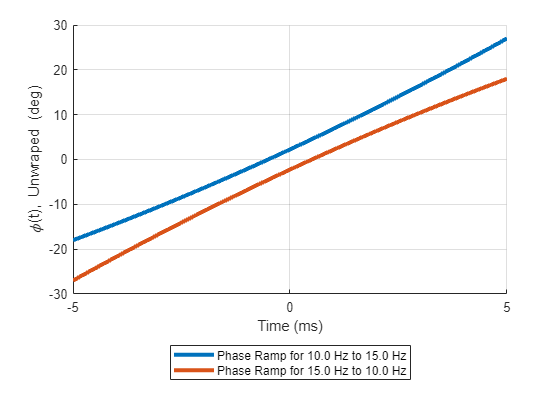


figure();
hold on
plot(t_test * 1e3, rad2deg(phase_ramps_fxs_by_freq_jump{1}(t_test)), LineWidth=3);
plot(t_test * 1e3, rad2deg(phase_ramps_fxs_by_freq_jump{2}(t_test)), LineWidth=3);
ylabel('\phi(t), Unwraped (deg)');
xlabel('Time (ms)');
xlim([ramp_t1, ramp_t2] * 1e3);
legend(compose("Phase Ramp for %.1f Hz to %.1f Hz", ...
    unique_freq_jumps(:, 1), unique_freq_jumps(:, 2)), ...
    Location="southoutside");
grid('on')

Misc Tests

syms x_sym x1_sym x2_sym real
teepee_sfx = 1 ...
    * (-1 * abs((4 * 1 / (x2_sym - x1_sym) ^ 2) ...
                        * (x_sym - ((x1_sym + x2_sym) / 2))) ...
              + (2 * 1 / (x2_sym - x1_sym)))

$$teepee\_sfx = -\frac{2}{x_{1,\mathrm{sym}}-x_{2,\mathrm{sym}}}-\frac{4\,\left|\frac{x_{1,\mathrm{sym}}}{2}+\frac{x_{2,\mathrm{sym}}}{2}-x_{\mathrm{sym}}\right|}{{\left(x_{1,\mathrm{sym}}-x_{2,\mathrm{sym}}\right)}^{2}}$$




teepee_fx = matlabFunction(subs(teepee_sfx, [x1_sym, x2_sym], [-1, 1]))

teepee_fx = function_handle with value:
    @(x_sym)-abs(x_sym)+1.0


teepee_fx = @(x) subplus(teepee_fx(x))

teepee_fx = function_handle with value:
    @(x)subplus(teepee_fx(x))


int_teepee_fx = @(x) double(subs(int_teepee_sub_sfx, x_sym, xx))

int_teepee_fx = function_handle with value:
    @(x)double(subs(int_teepee_sub_sfx,x_sym,xx))



xx = linspace(-2, 2, 1000)

xx =    -2.0000   -1.9960   -1.9920   -1.9880   -1.9840   -1.9800   -1.9760   -1.9720   -1.9680   -1.9640   -1.9600   -1.9560   -1.9520   -1.9479   -1.9439   -1.9399   -1.9359   -1.9319   -1.9279   -1.9239   -1.9199   -1.9159   -1.9119   -1.9079   -1.9039   -1.8999   -1.8959   -1.8919   -1.8879   -1.8839   -1.8799   -1.8759   -1.8719   -1.8679   -1.8639   -1.8599   -1.8559   -1.8519   -1.8478   -1.8438   -1.8398   -1.8358   -1.8318   -1.8278   -1.8238   -1.8198   -1.8158   -1.8118   -1.8078   -1.8038


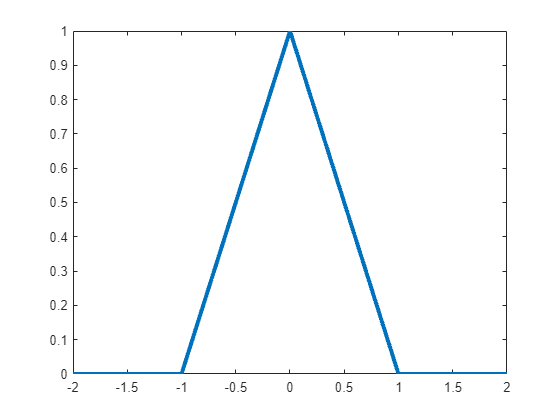

teepee_y = teepee_fx(xx);

figure();
plot(xx, teepee_y, LineWidth=3)

Visualizing Sigmoid Options

xx = linspace(-1.5, 1.5, 1000)

xx =    -1.5000   -1.4970   -1.4940   -1.4910   -1.4880   -1.4850   -1.4820   -1.4790   -1.4760   -1.4730   -1.4700   -1.4670   -1.4640   -1.4610   -1.4580   -1.4550   -1.4520   -1.4489   -1.4459   -1.4429   -1.4399   -1.4369   -1.4339   -1.4309   -1.4279   -1.4249   -1.4219   -1.4189   -1.4159   -1.4129   -1.4099   -1.4069   -1.4039   -1.4009   -1.3979   -1.3949   -1.3919   -1.3889   -1.3859   -1.3829   -1.3799   -1.3769   -1.3739   -1.3709   -1.3679   -1.3649   -1.3619   -1.3589   -1.3559   -1.3529


x1 = -1

x1 = -1

x2 = 1

x2 = 1

y1 = 0

y1 = 0

y2 = 1

y2 = 1

int_teepee_y = integrated_teepee(xx, x1, x2, y1, y2);

num_sigma = pi

num_sigma = 3.1416

clamped_erf_y = clamped_erf(xx, x1, x2, y1, y2, num_sigma);

half_sin_y = half_sin(xx, x1, x2, y1, y2);

style = '-'

style = '-'

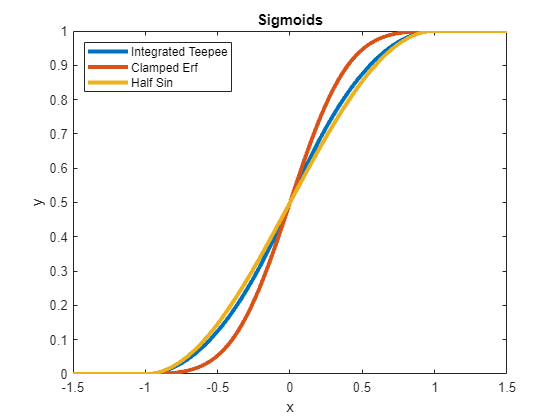


figure();
plot(xx, int_teepee_y, style, LineWidth=3)
hold on
plot(xx, clamped_erf_y, style, LineWidth=3)
plot(xx, half_sin_y, style, LineWidth=3)
title('Sigmoids');
ylabel('y')
xlabel('x')
legend({'Integrated Teepee', 'Clamped Erf', 'Half Sin'}, Location="northwest")

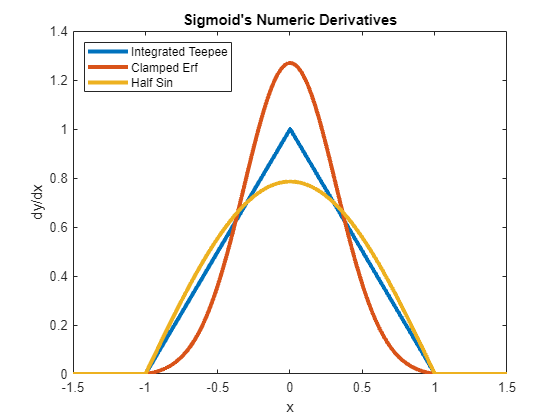


figure();
dx = xx(2) - xx(1);
d_int_teepee_y = [0, diff(int_teepee_y)] / dx;
d_clamped_erf_y = [0, diff(clamped_erf_y)] / dx;
d_half_sin_y = [0, diff(half_sin_y)] / dx;
plot(xx, d_int_teepee_y, style, LineWidth=3)
hold on
plot(xx, d_clamped_erf_y, style, LineWidth=3)
plot(xx, d_half_sin_y, style, LineWidth=3)
title('Sigmoid''s Numeric Derivatives');
ylabel('dy/dx');
xlabel('x')
legend({'Integrated Teepee', 'Clamped Erf', 'Half Sin'}, Location="northwest")

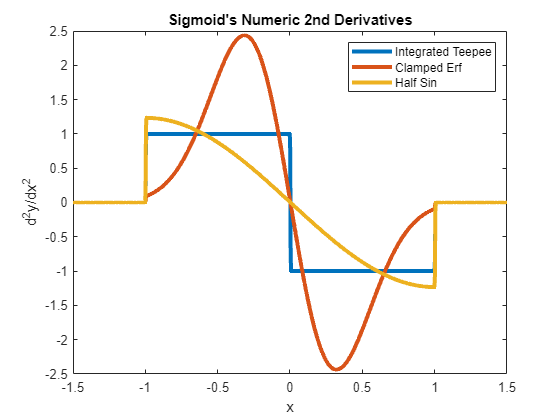


figure();
dd_int_teepee_y = [0, diff(d_int_teepee_y)] / dx;
dd_clamped_erf_y = [0, diff(d_clamped_erf_y)] / dx;
dd_half_sin_y = [0, diff(d_half_sin_y)] / dx;
plot(xx, dd_int_teepee_y, style, LineWidth=3)
hold on
plot(xx, dd_clamped_erf_y, style, LineWidth=3)
plot(xx, dd_half_sin_y, style, LineWidth=3)
title('Sigmoid''s Numeric 2nd Derivatives');
ylabel('d^2y/dx^2');
xlabel('x')
legend({'Integrated Teepee', 'Clamped Erf', 'Half Sin'})

Functions

function output = clamped_erf(x, x1, x2, y1, y2, num_sigma)
    % x2 must be greater than x1

    output = zeros(size(x), 'like', x);
    is_clip_1 = x < x1;
    is_clip_2 = x > x2;
    output(is_clip_1) = y1;
    output(is_clip_2) = y2;
    
    is_fx_defined = ~is_clip_1 & ~is_clip_2;
    if ~any(is_fx_defined)
        return
    end
    
    dx = x2 - x1;
    sigma = dx / (num_sigma * 2);
    mu = (x1 + x2) / 2;
     
    % ramp correction
    % cdf_fx = @(x) 1 / 2 * (1 + erf((x - mu) / (sigma * sqrt(2))));
    % 
    % err_val = [0 - cdf_fx(x1), 1 - cdf_fx(x2)];
    % correction_fx = @(x) err_val(1) + (diff(err_val) / dx * (x - x1));
    % sigmoid_fx = @(x) y1 + (y2 - y1) * (cdf_fx(x) + correction_fx(x));
    
    % clip correction
    % cdf_fx = @(x) 1 / 2 * (1 + erf((x - mu) / (sigma * sqrt(2))));
    %
    % err_val_1 = cdf_fx(x1);
    % err_val_2 = cdf_fx(x2) - err_val_1;
    % sigmoid_fx = @(x) y1 + ((y2 - y1) * (cdf_fx(x) - err_val_1) / err_val_2);

    % truncated redifinition
    cdf_fx = @(x) normcdf(x, mu, sigma);
    pdf_fx = @(x) normpdf(x, mu, sigma);
    cdf_x1 = cdf_fx(x1);
    cdf_x2 = cdf_fx(x2);
    pdf_x1 = pdf_fx(x1);
    auc_base = cdf_x2 - cdf_x1 - (pdf_x1 * dx);
    sigmoid_fx = @(x) y1 + ((y2 - y1) / auc_base ...
        * (cdf_fx(x) - cdf_x1 - (pdf_x1 * (x - x1))));

    output(is_fx_defined) = sigmoid_fx(x(is_fx_defined));
end

function output = integrated_teepee(x, x1, x2, y1, y2)
    output = zeros(size(x), 'like', x);
    
    isPreTeepee = x <= x1;
    output(isPreTeepee) = 0;
    isPostTeepee = x >= x2;
    output(isPostTeepee) = 1;
    isConstRegion = isPreTeepee | isPostTeepee;
    
    if ~all(isConstRegion)
        tMidpoint = (x1 + x2) / 2;
        dx = -x2 + x1;
        
        isXPrePeak = (x < tMidpoint) & ~isConstRegion;
        isXPostPeak = ~isXPrePeak & ~isConstRegion;
        
        output(isXPrePeak) = ...
            1.0 ./ dx .^ 2 .* (-x(isXPrePeak) + x1) .^ 2 .* 2.0;
        output(isXPostPeak) = ...
            (1.0 ./ dx .^ 2 .* (-x(isXPostPeak) + x2) .^ 2 .* -2.0) + 1;
    end
    
    output = y1 + (output * (y2 - y1));
end

function output = half_sin(x, x1, x2, y1, y2)
    output = zeros(size(x), 'like', x);
    is_clip_1 = x <= x1;
    is_clip_2 = x >= x2;
    output(is_clip_1) = 0;
    output(is_clip_2) = 1;

    is_fx_defined = ~is_clip_1 & ~is_clip_2;
    if any(is_fx_defined)
        delta_x = x2 - x1;
        half_sin_fx = @(x) (sin((2 * pi * (x - x1) / 2 / delta_x) - (pi / 2)) / 2) + (1 / 2);
        output(is_fx_defined) = half_sin_fx(x(is_fx_defined));
    end

    output = y1 + (output * (y2 - y1));
end

function y = wrapTo2PiStable(x, tol)
    y = wrapTo2Pi(x);
    y(y > ((2 * pi) - tol)) = 0;
end

function y = wrapToPiStable(x, tol)
    y = wrapToPi(x);
    y(y < (-pi + tol)) = pi;
end